# Damped Oscillation: Virus

syms vo b k m x(t) x1(t) x2(t);
assume(b>0);
assume(k>0);
assume(m>0);
Dx = diff(x,t);
D2x = diff(x,t,2);
b=0;
equ=D2x == -x*k/m - Dx*b/m

$$equ(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{k\,x\left(t\right)}{m}$$

cond = [x(0)==0, Dx(0)==vo];
dsolve(equ,cond);
k=0.5;
m=0.03;
b=0.1;
%b=0;
equn = D2x == -x*k/m - Dx*b/m

$$equn(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{10\,\frac{\partial }{\partial t}x\left(t\right)}{3}-\frac{50\,x\left(t\right)}{3}$$

vo = 0.1;                        
condn = [x(0)==0.1, Dx(0)==vo];
x2 = dsolve(equn, condn)

$$x2 = \frac{{\mathrm{e}}^{-\frac{5\,t}{3}}\,\cos\left(\frac{5\,\sqrt{5}\,t}{3}\right)}{10}+\frac{4\,\sqrt{5}\,{\mathrm{e}}^{-\frac{5\,t}{3}}\,\sin\left(\frac{5\,\sqrt{5}\,t}{3}\right)}{125}$$

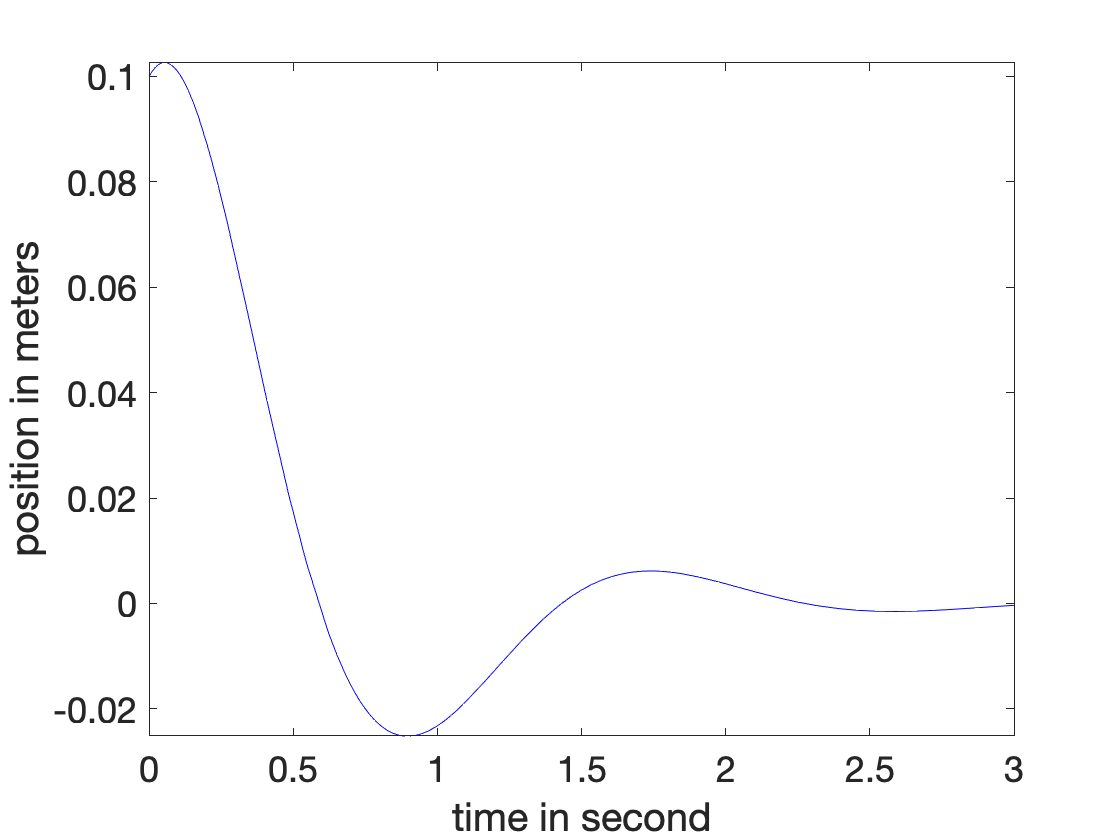

set(groot, 'DefaultAxesFontSize', 18);
figure(1)
fplot(x2, [0,3], '-b')
xlabel('time in second');
ylabel('position in meters');

v = diff(x2, t)

$$v = \frac{{\mathrm{e}}^{-\frac{5\,t}{3}}\,\cos\left(\frac{5\,\sqrt{5}\,t}{3}\right)}{10}-\frac{11\,\sqrt{5}\,{\mathrm{e}}^{-\frac{5\,t}{3}}\,\sin\left(\frac{5\,\sqrt{5}\,t}{3}\right)}{50}$$

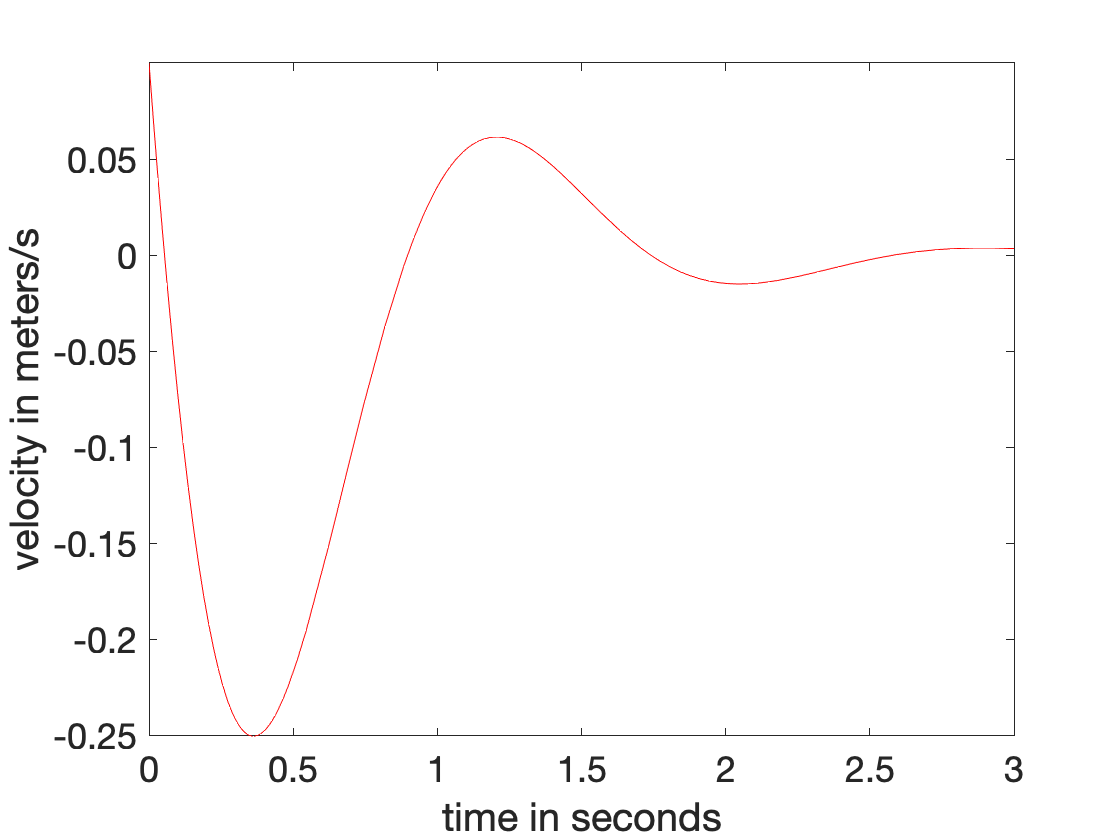

figure(2)
fplot(v, [0,3], '-r')
xlabel('time in seconds')
ylabel('velocity in meters/s')

figure(3)
fplot(x2, [0,3], '-b')
hold on 
fplot(v, [0,3], '-r')
xlabel('time in seconds')
ylabel(['position in m (blue)...' ...
    ' velocity in m/s (red)'])